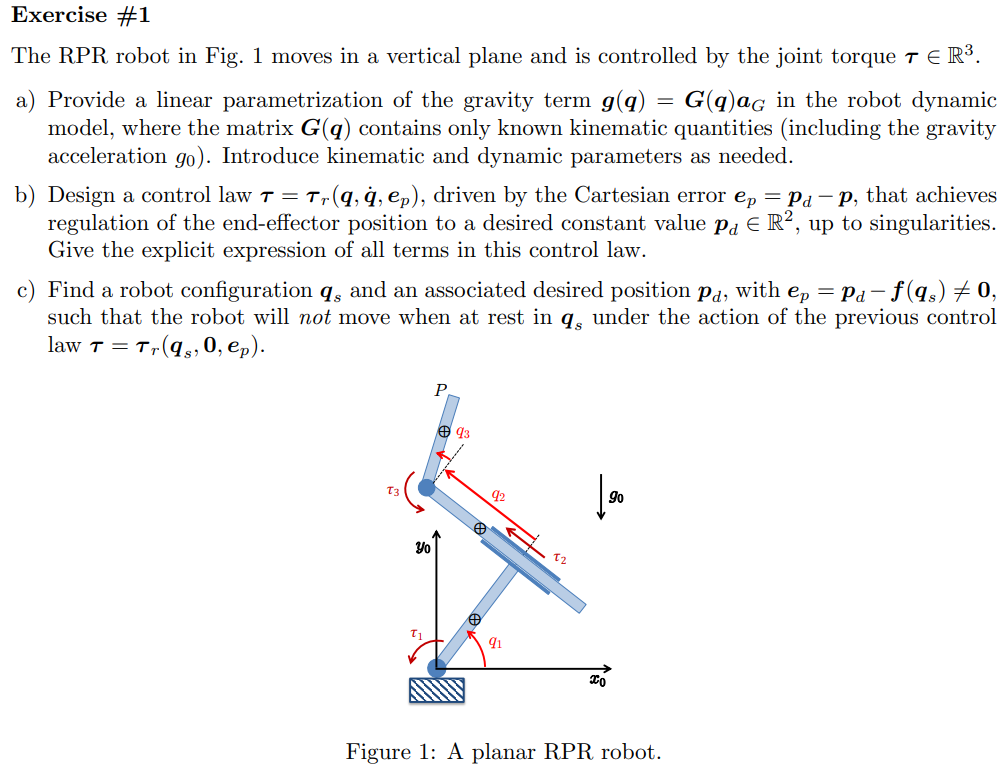

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 l_1 l_2 l_3 d_1 d_2 d_3 real
syms m_1 m_2 m_3  I_1 I_2 I_3 g0 positive

x1 = d_1*cos(q1);
y1 = d_1*sin(q1);

vx1 = diff(x1,q1)*q_dot_1+diff(x1,q2)*q_dot_2+diff(x1,q3)*q_dot_3;
vy1 = diff(y1,q1)*q_dot_1+diff(y1,q2)*q_dot_2+diff(y1,q3)*q_dot_3;

T1 = simplify(0.5*m_1*[vx1 vy1]*[vx1; vy1;]+0.5*I_1*q_dot_1^2)

$$T1 = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{d_{1}}^{2}+I_{1}\right)}{2}$$


x2 = l_1*cos(q1)-(q2-d_2)*sin(q1);
y2 = l_1*sin(q1)+(q2-d_2)*cos(q1);

vx2 = diff(x2,q1)*q_dot_1+diff(x2,q2)*q_dot_2+diff(x2,q3)*q_dot_3;
vy2 = diff(y2,q1)*q_dot_1+diff(y2,q2)*q_dot_2+diff(y2,q3)*q_dot_3;

T2 = simplify(0.5*m_2*[vx2 vy2]*[vx2; vy2;]+0.5*I_2*q_dot_1^2)

$$T2 = \frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(l_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}\right)\right)}^{2}}{2}$$


x3 = l_1*cos(q1)-(q2)*sin(q1)+d_3*sin(q1+q3);
y3 = l_1*sin(q1)+(q2)*cos(q1)+d_3*cos(q1+q3);

vx3 = diff(x3,q1)*q_dot_1+diff(x3,q2)*q_dot_2+diff(x3,q3)*q_dot_3;
vy3 = diff(y3,q1)*q_dot_1+diff(y3,q2)*q_dot_2+diff(y3,q3)*q_dot_3;
omega_3 = [q_dot_1+q_dot_3]

$$omega\_3 = {\dot{q}}_{1}+{\dot{q}}_{3}$$


T3 = 0.5*m_3*[vx3 vy3]*[vx3; vy3;]+0.5*I_3*[0 0 omega_3]*[0; 0; omega_3;]

$$T3 = \frac{m_{3}\,{\left({\dot{q}}_{2}\,\sin\left(q_{1}\right)+{\dot{q}}_{1}\,\left(q_{2}\,\cos\left(q_{1}\right)-d_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}+q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{1}\,\left(d_{3}\,\sin\left(q_{1}+q_{3}\right)-l_{1}\,\cos\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\right)-{\dot{q}}_{2}\,\cos\left(q_{1}\right)+d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{1}+q_{3}\right)\right)}^{2}}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}}{2}$$


T = T1+T2+T3

$$T = \frac{m_{3}\,{\left({\dot{q}}_{2}\,\sin\left(q_{1}\right)+{\dot{q}}_{1}\,\left(q_{2}\,\cos\left(q_{1}\right)-d_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}+q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{1}\,\left(d_{3}\,\sin\left(q_{1}+q_{3}\right)-l_{1}\,\cos\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\right)-{\dot{q}}_{2}\,\cos\left(q_{1}\right)+d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{1}+q_{3}\right)\right)}^{2}}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{d_{1}}^{2}+I_{1}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(l_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}\right)\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = simplify([M11, M12, M13; M21, M22, M23; M31, M32, M33])

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{d_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+m_{2}\,{q_{2}}^{2}+m_{3}\,{q_{2}}^{2}-2\,d_{2}\,m_{2}\,q_{2}-2\,d_{3}\,m_{3}\,q_{2}\,\sigma_{3}-2\,d_{3}\,l_{1}\,m_{3}\,\sigma_{4} & \sigma_{2} & \sigma_{1}\\ \sigma_{2} & m_{2}+m_{3} & -d_{3}\,m_{3}\,\sigma_{4}\\ \sigma_{1} & -d_{3}\,m_{3}\,\sigma_{4} & m_{3}\,{d_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{d_{3}}^{2}\,m_{3}-d_{3}\,m_{3}\,q_{2}\,\sigma_{3}-d_{3}\,l_{1}\,m_{3}\,\sigma_{4}\\ \sigma_{2}=l_{1}\,m_{2}+l_{1}\,m_{3}-d_{3}\,m_{3}\,\sigma_{4}\\ \sigma_{3}=\cos\left(2\,q_{1}+q_{3}\right)\\ \sigma_{4}=\sin\left(2\,q_{1}+q_{3}\right) \end{array}$$


% Coriolis and Centrifugal terms
q  = [q1; q2; q3;];
dq = [q_dot_1; q_dot_2; q_dot_3;];
C = sym(zeros(3,3));

for i = 1:3
    for j = 1:3
        tmp = 0;
        for k = 1:3
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\begin{array}{l} \left(\begin{array}{ccc} -{\dot{q}}_{2}\,\sigma_{2}-{\dot{q}}_{3}\,\sigma_{1}-{\dot{q}}_{1}\,\left(2\,d_{3}\,l_{1}\,m_{3}\,\sigma_{4}-2\,d_{3}\,m_{3}\,q_{2}\,\sigma_{3}\right) & -{\dot{q}}_{1}\,\sigma_{2} & -d_{3}\,m_{3}\,\left(l_{1}\,\sigma_{4}-q_{2}\,\sigma_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ -{\dot{q}}_{1}\,\left(m_{2}\,q_{2}-d_{2}\,m_{2}+m_{3}\,q_{2}+d_{3}\,m_{3}\,\sigma_{4}\right)-d_{3}\,m_{3}\,{\dot{q}}_{3}\,\sigma_{4} & 0 & -d_{3}\,m_{3}\,\sigma_{4}\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ -{\dot{q}}_{1}\,\sigma_{1}-d_{3}\,m_{3}\,{\dot{q}}_{2}\,\sigma_{4} & -d_{3}\,m_{3}\,{\dot{q}}_{1}\,\sigma_{4} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{3}\,l_{1}\,m_{3}\,\sigma_{4}-d_{3}\,m_{3}\,q_{2}\,\sigma_{3}\\ \sigma_{2}=d_{2}\,m_{2}-m_{2}\,q_{2}-m_{3}\,q_{2}+d_{3}\,m_{3}\,\sigma_{4}\\ \sigma_{3}=\sin\left(2\,q_{1}+q_{3}\right)\\ \sigma_{4}=\cos\left(2\,q_{1}+q_{3}\right) \end{array}$$

disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\begin{array}{l} \left(\begin{array}{c} 2\,m_{2}\,q_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}-2\,d_{2}\,m_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+2\,m_{3}\,q_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}-2\,d_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sigma_{1}-2\,d_{3}\,l_{1}\,m_{3}\,{{\dot{q}}_{1}}^{2}\,\sigma_{1}-d_{3}\,l_{1}\,m_{3}\,{{\dot{q}}_{3}}^{2}\,\sigma_{1}+2\,d_{3}\,m_{3}\,q_{2}\,{{\dot{q}}_{1}}^{2}\,\sigma_{2}+d_{3}\,m_{3}\,q_{2}\,{{\dot{q}}_{3}}^{2}\,\sigma_{2}-2\,d_{3}\,l_{1}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\sigma_{1}+2\,d_{3}\,m_{3}\,q_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\sigma_{2}\\ -{\dot{q}}_{1}\,\left({\dot{q}}_{1}\,\left(m_{2}\,q_{2}-d_{2}\,m_{2}+m_{3}\,q_{2}+d_{3}\,m_{3}\,\sigma_{1}\right)+d_{3}\,m_{3}\,{\dot{q}}_{3}\,\sigma_{1}\right)-d_{3}\,m_{3}\,{\dot{q}}_{3}\,\sigma_{1}\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ -d_{3}\,m_{3}\,{\dot{q}}_{1}\,\left(2\,{\dot{q}}_{2}\,\sigma_{1}+l_{1}\,{\dot{q}}_{1}\,\sigma_{1}-q_{2}\,{\dot{q}}_{1}\,\sigma_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,q_{1}+q_{3}\right)\\ \sigma_{2}=\sin\left(2\,q_{1}+q_{3}\right) \end{array}$$


% Gravity terms
U1 = m_1*g0*(d_1*sin(q1))

$$U1 = d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

U2 = m_2*g0*(l_1*sin(q1)+(q2-d_2)*cos(q1))

$$U2 = g_{0}\,m_{2}\,\left(l_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)$$

U3 = m_3*g0*(l_1*sin(q1)+(q2)*cos(q1)+d_3*sin(q1+q3))

$$U3 = g_{0}\,m_{3}\,\left(d_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\right)$$

U = [U1+U2+U3]

$$U = g_{0}\,m_{2}\,\left(l_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+g_{0}\,m_{3}\,\left(d_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

g_q = simplify([diff(U,q1); diff(U,q2); diff(U,q3);])

$$g\_q = \left(\begin{array}{c} g_{0}\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left(d_{2}-q_{2}\right)\right)+g_{0}\,m_{3}\,\left(d_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)\\ g_{0}\,\cos\left(q_{1}\right)\,\left(m_{2}+m_{3}\right)\\ d_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{3}\right) \end{array}\right)$$



P = [x3; y3;];
J = jacobian(p,[q1,q2,q3])

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{3}-\sigma_{1}-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sigma_{3}-\sigma_{1}-\sin\left(q_{1}+q_{2}\right) & -\sigma_{3}-\sigma_{1}\\ \sigma_{4}+\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \sigma_{4}+\sigma_{2}+\cos\left(q_{1}+q_{2}\right) & \sigma_{4}+\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

det_J = simplify(det(J.'*J))

$$det\_J = 0$$